### 1`、按要求进行与矩阵相关的操作。`

#### **(1) 构造两个矩阵。**

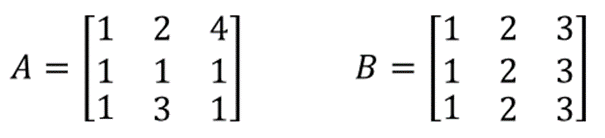

% 你的答案
A = [1 2 4; 1 1 1; 1 3 1];
B = [1 2 3; 1 2 3; 1 2 3];

% 思考: 矩阵A能否使用 ones() 并修改特定元素来构造
A = ones(3);
A(1,2) = 2;
A(1,3) = 4;
A(3,2) = 3;
% 思考: 搜索 repmat() 如何使用，并用它来构造矩阵B
B = repmat([1 2 3],3,1)

B =      1     2     3
     1     2     3
     1     2     3


#### (2) `将`A`和`B`中``所有位置对应的元素相加和相乘``，分别赋值给`sum_AB`和`dpro_AB`。`

% 你的答案
% 提示: 点乘 由点和乘组成 尝试 .*
sum_AB = A + B

sum_AB =      2     4     7
     2     3     4
     2     5     4


dpro_AB = A .* B

dpro_AB =      1     4    12
     1     2     3
     1     6     3


#### (3) `将矩阵`B`转置``并赋值给`BT`，让矩阵`A`和`BT`两个``矩阵相乘``并赋值给`pro_ABT`。`

% 你的答案
% 提示: 在表示矩阵的变量后加一个 ' 试试
BT = B'

BT =      1     1     1
     2     2     2
     3     3     3


pro_ABT = A * BT

pro_ABT =     17    17    17
     6     6     6
    10    10    10


#### (4) `将矩阵`A`和`B`横向拼接``在一起，赋值给矩阵`C；纵向拼接在一起，赋值给矩阵VC。

% 你的答案
% 提示: 将两个数组并排放在一个 [] 内。两个数组之间加上 ; 会怎样呢
C = [A B]

C =      1     2     4     1     2     3
     1     1     1     1     2     3
     1     3     1     1     2     3


VC = [A; B]

VC =      1     2     4
     1     1     1
     1     3     1
     1     2     3
     1     2     3
     1     2     3



% 思考: 搜索 cat() 如何使用，并完成上述操作
C = cat(2, A, B)

C =      1     2     4     1     2     3
     1     1     1     1     2     3
     1     3     1     1     2     3


VC = cat(1, A, B)

VC =      1     2     4
     1     1     1
     1     3     1
     1     2     3
     1     2     3
     1     2     3


#### (5) `请将矩阵`C`第`3`行第`2`列``的元素赋值给`**a**`；将矩阵的``第`4`列``提取出来赋值给`**b**`；将矩阵``第`1`行的元素每隔`1`个``提取出来赋值给`**c**`。`

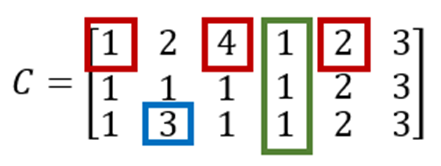

% 你的答案
% 提示: m:n 从m到n; m:s:n 从m到n步长为s; : 从开始到结束
a = C(3,2)

a = 3

b = C(:,4)

b =      1
     1
     1


c = C(1,1:2:end)

c =      1     4     2



% 思考: C(1,[2,3,4,6])会提取出来什么
% [2,4,1,3]
% 思考: C([1,3],[2,5])会提取出来什么
% [2,2;3,2]

#### (6) `运行指令：`

#### (i) C > 2.5

#### (ii) C(C > 2.5)

#### (iii) find(C > 2.5)

#### `说说他们输出的含义。`

% 你的答案
C > 2.5

ans = 3×6 logical 数组
   0   0   1   0   0   1
   0   0   0   0   0   1
   0   1   0   0   0   1


C(C > 2.5)

ans =      3
     4
     3
     3
     3


find(C > 2.5)

ans =      6
     7
    16
    17
    18


(i) 对C中各个元素进行判断，符合不等式输出1，不符合输出0，输出为logical类型

(ii) 输出C中符合不等式的元素

(iii) 输出C中符合不等式的元素的线性索引

% 思考: [row,col] = find(C > 2.5) 得到了什么结果。搜索 find() 文档

得到了符合不等式的元素对应的行列下标，分别存储在row和col中

% 思考：ind2sub 有什么功能，如何使用

将元素在某个大小的矩阵中的线性索引转化为对应的行列下标

### 2`、以下是某名被试在完成一项按键反应任务时的实验数据，请按要求进行整理。`

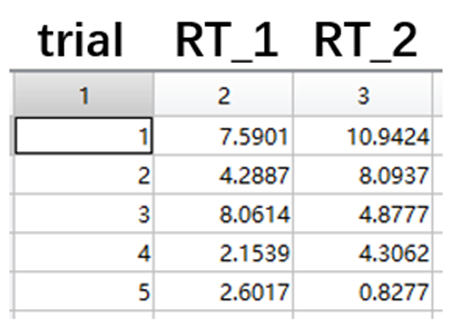

#### (1) `将数据“`sub_001.mat`”读入`matlab`中。`

% 你的答案
% 提示: load()
load('sub_001.mat')

% 思考: 什么是绝对路径，什么是相对路径？ 

绝对路径从根目录开始，相对路径从工作目录开始

% 思考: 你的答案是哪一种写法？另一种写法怎么写呢？

答案为相对路径，另一种写法为load('C:\Users\86137\Desktop\Class\MATLAB\homework\matlab_exe1')

% 思考：windows和mac相比，二者matlab中绝对路径的表达有何不同？

#### (2) `数据中的值若为`999`，则代表数据缺失。请将数据缺失的试次``找出``并``删除``。`

% 你的答案
% 提示: 搜索 find() 文档; 删除某行某列可以使其等于 []
[row, col] = find(data == 999)

row =      6
    17
    12


col =      2
     2
     3


data(row,:) = []

data =     1.0000    7.5901   10.9424
    2.0000    4.2887    8.0937
    3.0000    8.0614    4.8777
    4.0000    2.1539    4.3062
    5.0000    2.6017    0.8277
    7.0000    6.0881    9.3463
    8.0000    5.6527    0.7706
    9.0000    4.2657    2.7290
   10.0000    7.5406    3.1000
   11.0000    1.9758    0.7143



% 思考: 数据缺失的试次并不是按顺序排列，搜索 sort() 如何使用，
% 并将试次编号按升序和降序进行排列。
sort(row)
sort(row, "descend")
% 思考: 如何判断是否清理干净, 搜索 ismember() 文档。
ismember(999,data)

ans = logical
   0


#### (3) `计算每个试次前后两次按键反应时之差,并将数据作为新的一列添加在最后。`

% 你的答案
newRT = data(:,3) - data(:,2)

newRT =     3.3522
    3.8050
   -3.1838
    2.1523
   -1.7740
    3.2582
   -4.8821
   -1.5367
   -4.4406
   -1.2615


data = [data newRT]

data =     1.0000    7.5901   10.9424    3.3522
    2.0000    4.2887    8.0937    3.8050
    3.0000    8.0614    4.8777   -3.1838
    4.0000    2.1539    4.3062    2.1523
    5.0000    2.6017    0.8277   -1.7740
    7.0000    6.0881    9.3463    3.2582
    8.0000    5.6527    0.7706   -4.8821
    9.0000    4.2657    2.7290   -1.5367
   10.0000    7.5406    3.1000   -4.4406
   11.0000    1.9758    0.7143   -1.2615


#### (4) `将得到的数据以“`sub_001_clean.mat`”的名字储存在新建文件夹“`data_clean`”中。`

% 你的答案
% 提示: 新建文件夹 mkdir(); 保存数据 save()
mkdir('data_clean')

save('.\data_clean\sub_001_clean.masub_001_clean.mat',"data")


% 思考: 写一个完整的绝对路径通常很繁琐，
% 代码 save('.\data_clean\sub_001_clean.mat','data') 可以达到相同效果
% 其中 . 代表什么? 
% 工作目录？
% 思考: 在 command window 中输入 cd .. 其中 .. 代表什么？
% 返回上一级目录